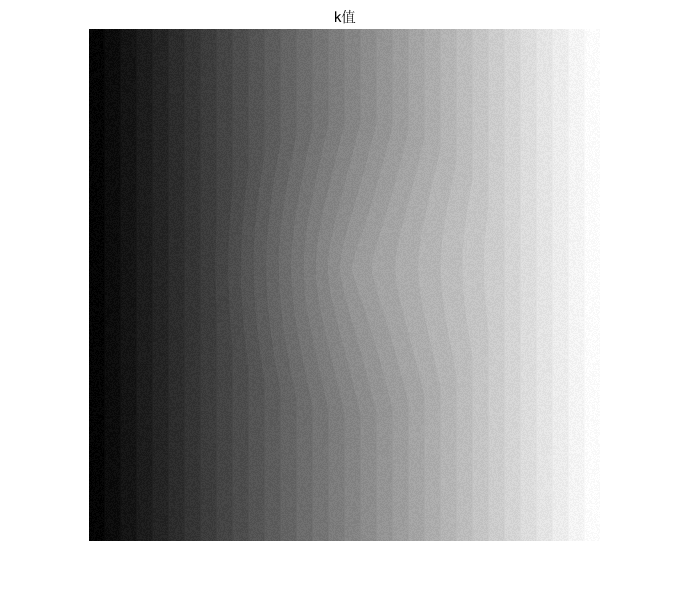

clc
clear all
clf
% all_k=1200;
% k=0;
% %%%通过比较K取整和不取整的结果，最后决定对k不取整，这样才能恢复准确度较高的相位
% for i=1:all_k
% k=k+1;
% disp('k');
% path_k_phi_wrapped_high=['E:\liyimingPCL\博士课题\实验记录-源代码+过程\3.14-基本工件几何体仿真\code\new\phi_wrapped_high\', num2str(k), '.mat'];
% phi_wrapped_high1=load(path_k_phi_wrapped_high);
% phi_wrapped_high=phi_wrapped_high1.phi_wrapped_high;
% 
% path_k_phi_unwrapped_no_noisy=['E:\liyimingPCL\博士课题\实验记录-源代码+过程\3.14-基本工件几何体仿真\code\new\phi_unwrapped_no_noisy\', num2str(k), '.mat'];
% phi_unwrapped_no_noisy1=load(path_k_phi_unwrapped_no_noisy);
% phi_unwrapped_no_noisy=phi_unwrapped_no_noisy1.phi_unwrapped;
% % get_k=round((phi_unwrapped_no_noisy-phi_wrapped_high)/(2*pi));
% get_k_int=round((phi_unwrapped_no_noisy-phi_wrapped_high)/(2*pi));
% path=['E:\liyimingPCL\博士课题\实验记录-源代码+过程\3.14-基本工件几何体仿真\code\new\get_k_int\',num2str(k), '.mat'];
% save(path, 'get_k_int');
% end


% 
%%%%%%%%%%%%下面的程序是对生成的K值进行验证%%%%%%%%%%%%%%%%%%%%%%%
kk1=load('E:\liyimingPCL\博士课题\实验记录-源代码+过程\3.14-基本工件几何体仿真\code\new\get_k_int\777.mat');

get_k=kk1.get_k_int;
figure;
imshow(get_k,[]);
title('k值')

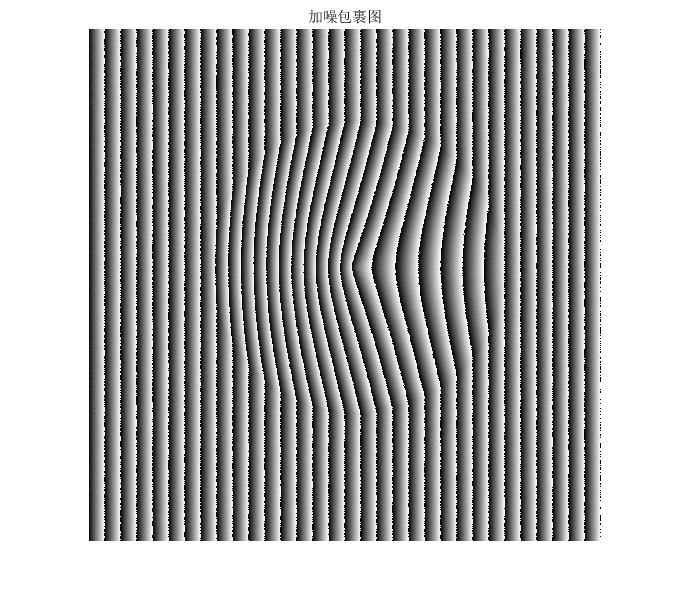


phi_wrapped_high1=load('E:\liyimingPCL\博士课题\实验记录-源代码+过程\3.14-基本工件几何体仿真\code\new\phi_wrapped_high\777.mat');

phi_wrapped_high=phi_wrapped_high1.phi_wrapped_high;
figure;
imshow(phi_wrapped_high,[]);
title('加噪包裹图')

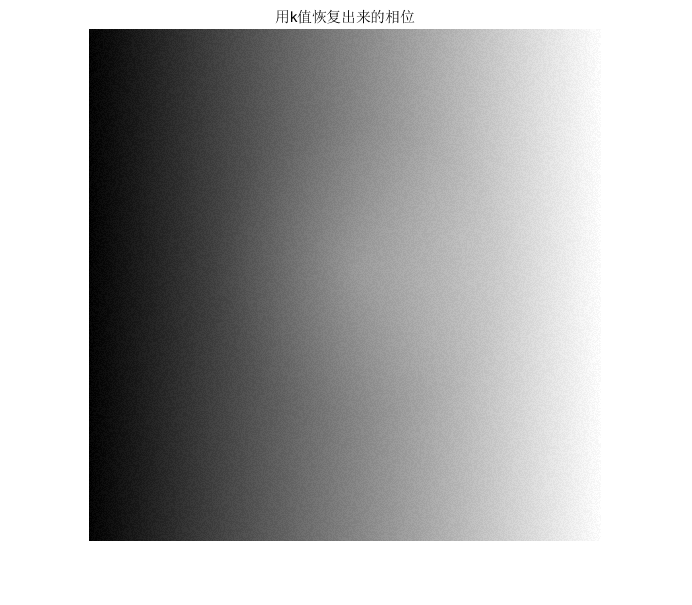



phi_unwrapped_no_noisy1=load('E:\liyimingPCL\博士课题\实验记录-源代码+过程\3.14-基本工件几何体仿真\code\new\phi_unwrapped_no_noisy\777.mat','phi_unwrapped');
phi_unwrapped_no_noisy=phi_unwrapped_no_noisy1.phi_unwrapped;
% % get_k=round((phi_unwrapped_no_noisy-phi_wrapped_high)/(2*pi));
% get_k=(phi_unwrapped_no_noisy-phi_wrapped_high)/(2*pi);
% figure;
% imshow(get_k,[]);
% title('K 值')

r_unwrapped=phi_wrapped_high+get_k*2*pi;
figure;
imshow(r_unwrapped,[]);
title('用k值恢复出来的相位')

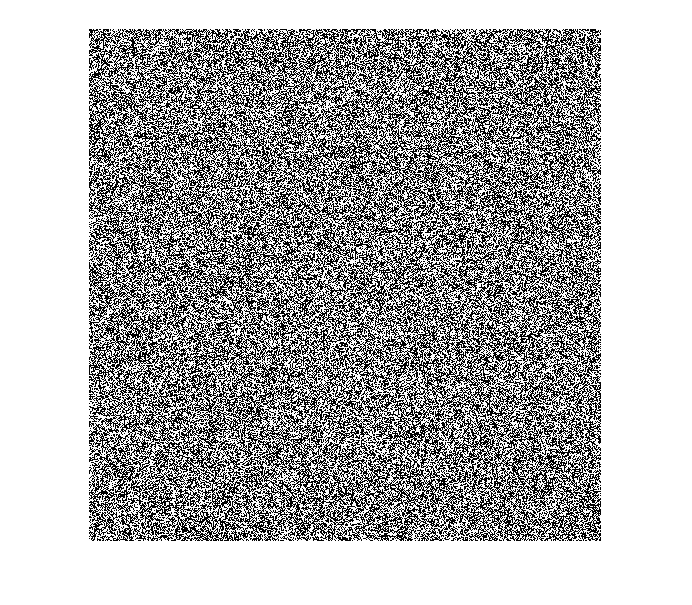

r_error=phi_unwrapped_no_noisy-r_unwrapped;
plot(r_error(350,:),'*');xlabel('像素u/pixel');ylabel('相位/rad'); 
title('误差——恢复出来的相位')
A=pi*ones(512,512);

% r_error = wdenoise2(r_error);%小波去噪
figure;
imshow(r_error,[]);

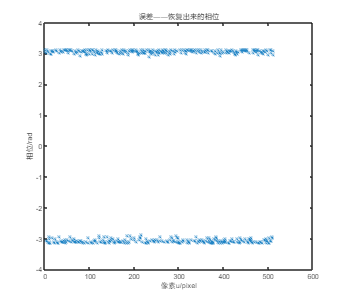

r_errorA=r_error+A;
figure;
imshow(r_errorA,[]);
plot(r_errorA(350,:),'*');xlabel('像素u/pixel');ylabel('相位/rad'); 